# F2_Run_Select_Designs.m

**Goal:** From local sensitivity analyses, pick what would have the best efficacy with the least number of parameter perturbed.

**Requirements:**

MATLAB Toolboxes: Parallel Computing, Bioinformatics, Symbolic Math

Custom Scripts: Add the `probiotic_code/` folder to your path

Model inputs as defined in `define_Common_Simulation_Inputs `(*Defines virtual patient population, simulation inputs)*

*Functions:*` simulate_CST_probiotic_object.m, plot_SelectProbioticDesigns.m, superbar.m`: If you do not have superbar, the plots wil not be generated. Superbar can be downloaded here: [https://www.mathworks.com/matlabcentral/fileexchange/57499-superbar](https://www.mathworks.com/matlabcentral/fileexchange/57499-superbar) 

## 1. Load Model Defaults

clear; clc;
output_fdr = 'result_workspaces/';
ws_name = 'input_files/SSConfig-Analysis-HMP-Virtual-Population.mat';
simulationType = "base";
[POPinfo,PROBinfo,~,SIMinfo] = define_Common_Simulation_Inputs(ws_name,simulationType);
[param_names,~,sp_cols,~] = get_naming_terms();

`POPinfo`: struct that defines virtual patient population

- `virtualPatientParameter`s: # patients x 20 parameter matrix generated by LHS

- `virtualPatientComposition`: 1 x # patients cell of analytically predicted steady-state absolute abundances of nAB, Li, oLB (predicted without considering probiotic in community)

`PROBinfo`: struct that defines probiotic parameters

- dose: absolute abundance of probiotic when dosed into the base community (selected from relative abundance data observed in Dausset et al. 2018)

- numberDoses: total number of doses given

- doseFrequency: time separation (days) between each dose

`SIMinfo`: struct that defines simulation inputs

- `startProbiotic`: time point after simulation begins to start probiotic therapy

- `stopSimulation`: time point to end simulation relative to the last day of probiotic treatment

- ` initialComposition`: scaling factor to "displace" from the predicted composition (POPinfo.virtualPatientComposition). For example, 0.01 is a 1% decrease in abundance and 0.05 is a 0.5% increase from the predicted abundance

- `alteredParamIndex`: indexes of probiotic-related parameters relative to the full parameter list

- `paramAlteration`: new value for probiotic parameters (a 1 x length alteredParamIndex array of values)

- `paramAlterationType`: 'None' (use LHS probiotic parameter, ignore paramAlteration values), 'fold addition' (scale LHS probiotic parameter (LP) + paramAlteration * LP,  'absolute' (set to exact value in paramAlteration)

- `ODEoptions`: "options" input for ode solvers

- `ODEsolver:` ODE solver function handle (e.g., @ode45, @ode15s)

## 2. Run Select Probiotic Designs

Define the selected perturbations

- `pidx_list:` cell array with the index of the probiotic parameters to change ([1] kgrow-P, [2] nAB->P, [3] Li ->P, [4] oLB->P [5] P->nAB [6] P->Li [7] P->oLB [8] P->P). Multiple indexes can be indicated.

- `mag:` magnitude of the value to be altered for inter-species interaction terms.

- `kgr_mag`: magnitude for kgrow values

- `pert_list`: cell array with the directionality for the perturbation change. NaN indicates no parameter change all (null probriotic), -1 indicates a negative change, 1 indicates a positive change, Cell array entries should be the same size as respecitive pidx_list entries. Scale kgr_mag for growth term within this array.

- `base_params`: null probiotic parameter values

pidx_list = {1,2, 5, [2 5], [1 2 5], [2 5], 7, [5 7],[5 6 7]}; % parameter indexes
mag = 0.01; % magnitude
kgr_mag = 0.8; % final growth rate
pert_list = {NaN,1,-1,[1 -1],[kgr_mag/mag 1 -1],[-1 -1],1,[-1 1],[-1 -1 1]}; % directionality
base_params = [0.5 0 0 0 0 0 0 -0.022]; % Null Probiotic
output_ws_nm = 'F2_Select_Probiotic_Designs.mat';

Run the selected perturbations:

t = tic;
numVirtualPatients = length(POPinfo.virtualPatientComposition);
all_select_outcomes = NaN(length(pidx_list),numVirtualPatients,8,5);
all_warnall = NaN(length(pidx_list),numVirtualPatients);
for pert_id = 1:length(pidx_list)
    SIMinfo.paramAlteration = base_params; 
    if ~isnan(pert_list{pert_id})
        SIMinfo.paramAlteration(pidx_list{pert_id}) = mag*pert_list{pert_id};
    end

    [select_outcomes,nonBVflag,tall,yall,warnall,...
           dose_lbls] = simulate_CST_probiotic_object(POPinfo,PROBinfo,SIMinfo);

    all_select_outcomes(pert_id,:,:,:) = select_outcomes;
    all_warnall(pert_id,:) = warnall == "";

    save(strcat(output_fdr,output_ws_nm),'all_select_outcomes','all_warnall',...
        'POPinfo','PROBinfo','SIMinfo','base_params',...
        'pidx_list','pert_list','mag','kgr_mag','pert_id')
end

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to the parallel pool (number of workers: 6).
> In ode15s (line 723)
In <a href="matlab:matlab.internal.language.introspective.errorDocCallback('parallel_function>make_general_channel/channel_general', '/Applications/MATLAB_R2022b.app/toolbox/matlab/lang/parallel_function.m', 837)" style="font-weight:bold

tend = toc(t);
disp(strcat(num2str(tend/60)," minutes"))

7.11minutes


Outputs saved include:

- `all_select_outcomes`: 4D array [# perturbations x # subjects x # evaluations points x # model speices + 1]. In this example it would be an 9 x 2000 x 8 x 5 double. The first index should be equivalent to the length of pidx_list/pert_list. Default number of evaluation points is 8 (time points where abundance measurement is collected, the last dimension is the time point and the species abundance. 

- `all_warnall`: 2D array [# perturbations x # subjects], index of 1 means no ODE solver warning, index of 0 indicates there was a integration warning

## 3. Plot Results

Results plotted are selected strains based on the local sensitivity analyses to evaluate for differences in efficacy.

On the left plot:

- Null Probiotic (considered a control)

- 1p: Traditional (1 parameter change; Null with P-> nAB set to -0.01)

- 1p: Best/Non-Traditional (1 parameter change; Null with nAB -> set to 0.01)

- 2p: Best (2 parameter change: null with P-> nAB set to -0.01; nAB -> set to 0.01)

- 3p: Best (3 parameter change: null with P-> nAB set to -0.01; nAB -> set to 0.01; kgrow-P set to 0.8)

- 2p: Counter (Example to demonstrate that if nAB -> P is negative, it can counteract the benefit of a negative value for P->nAB)

Below the plot is a heatmap describing what is written above a description of each simulation (white = no change, green = -0.01, pink = 0.01). 

The right plot aims to demonstrate differences in boosting endogenous *Lactobacillus *spp., but the changes are moderate.

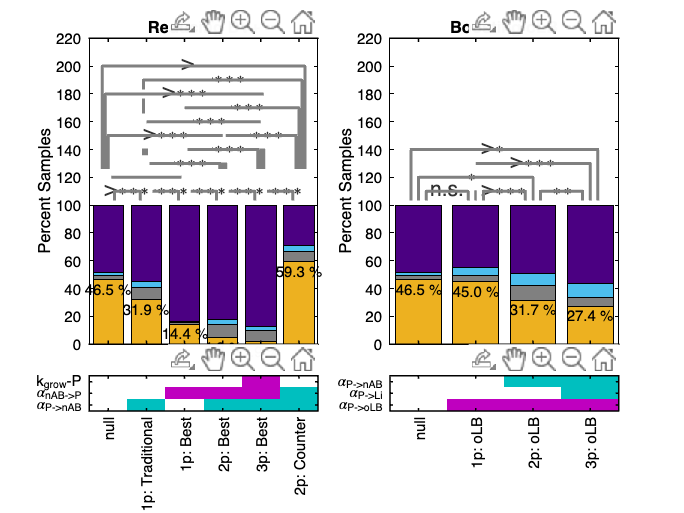

output_fdr = 'result_workspaces/F2/';

load(strcat(output_fdr,'F2_Select_Probiotic_Designs.mat'))
time_id = 8; % timepoint (8 = 12mo)
gr1 = [0 2 1 3 4 5]+1; % indexes for first plot
gr2 = [0 6:8]+1; % indexes for second plot
pert_names = {'null','1p: Best','1p: Traditional','2p: Best','3p: Best','2p: Counter','1p: oLB','2p: oLB','3p: oLB'};
    
figure;
[allCounts,pChiDfAllResponses, pChiDfBvResponses] = plot_SelectProbioticDesigns(pidx_list,...
    pert_list,pert_names,gr1,gr2,all_select_outcomes,all_warnall,...
    time_id);

The `plot_SelectProbioticDesigns` function also outputs model resuts at a given time point (default is 12 mo).

- `allCounts`: # desgins x 4 double [Rows: combinations of parameters, Columns: response type, nAB dominated, Li dominated, oLB dominated, Probiotic dominated for the 2000 subjects, with subjects where there was a integration error removed]

- `pChiDfAllResponses`: # designs x 3 double [Rows: combinations of parameters, Colums: P-vaue, Chi-square statistic, degrees of freedom] for a chi-square test comparing all four response types

- `pChiDfBVResponses`: # designs x 3 double [Rows: combinations of parameters, Colums: P-vaue, Chi-square statistic, degrees of freedom] for a chi-square test comparing BV+ (nAB dominant) vs BV- negative (Li, oLB or Probiotic dominated responses)